- Поиск глобального минимума  на основе необходимого и достаточного условий:

- 1  Без ограничений 

syms x u lambda;
Jx_u=8*x^2+6*u^2+4*x*u+x+3*u-10;
cx_u=3*x-2*u^2+1; 

grad_x=diff(Jx_u,x)==0

$$grad\_x = 4\,u+16\,x+1=0$$

grad_u=diff(Jx_u,u)==0

$$grad\_u = 12\,u+4\,x+3=0$$

x=solve([grad_x;grad_u]).x

$$x = 0$$

u=solve([grad_x;grad_u]).u

$$u = -\frac{1}{4}$$

Jx_u_min=8*x^2+6*u^2+4*x*u+x+3*u-10

$$Jx\_u\_min = -\frac{83}{8}$$

- 2  С ограничениями в виде равенства с${\left(x,u\right)}=0$


syms x u lambda;
L=Jx_u+lambda*cx_u

$$L = 3\,u+x+\lambda \,\left(-2\,u^{2}+3\,x+1\right)+4\,u\,x+6\,u^{2}+8\,x^{2}-10$$


gradL_x=diff(L,x)==0;
gradL_u=diff(L,u)==0;
gradL_lambda=diff(L,lambda)==0;
gradL=[gradL_lambda; gradL_x; gradL_u]

$$gradL = \left(\begin{array}{c} -2\,u^{2}+3\,x+1=0\\ 3\,\lambda +4\,u+16\,x+1=0\\ 12\,u+4\,x-4\,\lambda \,u+3=0 \end{array}\right)$$

**gradL забить в Вольфрам, внизу вписать ответы в переменные**

x=-0.262821;
u=-0.325221;
lambda=1.50201;

Jx_u_min_L=8*x^2+6*u^2+4*x*u+x+3*u-10

Jx_u_min_L = -9.7094

- 3  С ограничениями в виде неравенства $c{\left(x,u\right)}\le 0$

Лагранжиан идентичен полученному в 1.2:

syms x u lambda;
L=Jx_u+lambda*cx_u

$$L = 3\,u+x+\lambda \,\left(-2\,u^{2}+3\,x+1\right)+4\,u\,x+6\,u^{2}+8\,x^{2}-10$$

gradL_x=diff(L,x)==0;
gradL_u=diff(L,u)==0;
gradL_lambda=diff(L,lambda)<=0;
gradL=[gradL_lambda; gradL_x; gradL_u; lambda>=0; lambda*diff(L,lambda)==0]

$$gradL = \left(\begin{array}{c} -2\,u^{2}+3\,x+1\leq 0\\ 3\,\lambda +4\,u+16\,x+1=0\\ 12\,u+4\,x-4\,\lambda \,u+3=0\\ 0\leq \lambda \\ \lambda \,\left(-2\,u^{2}+3\,x+1\right)=0 \end{array}\right)$$

**gradL забить в Вольфрам, внизу вписать ответы в переменные**

x=-0.262821;
u=-0.325221;
lambda=1.50201;

Jx_u_min_L=8*x^2+6*u^2+4*x*u+x+3*u-10

Jx_u_min_L = -9.7094

2. Градиентный поиск минимума критерия качества:

syms x u lambda;
J1x_u=Jx_u;


H=[4 16;12 4];
x0=[0;0]

x0 =      0
     0


Hinv=inv(H);
gradJ0=[1;3];

n = 3;
J=zeros(1,n+1);
J(1) = 8*x0(1)^2+6*x0(2)^2+4*x0(1)*x0(2)+x0(1)+3*x0(2)-10;
for i = 1:n
    xn = x0 - Hinv*gradJ0;
    x0 = xn;
    gradJ0 = [4*x0(2) + 16*x0(1) + 1; 12*x0(2) + 4*x0(1) + 3];
    J(i+1) = 8*x0(1)^2+6*x0(2)^2+4*x0(1)*x0(2)+x0(1)+3*x0(2)-10;
end
J

J =   -10.0000   -9.7500   -7.8750   -0.3750


xn

xn =    -1.0000
    0.7500


x0 = [0;0];
gradJ0 = [4*x0(2) + 16*x0(1) + 1; 12*x0(2) + 4*x0(1) + 3];
y = 0.1;

n = 50;
J = zeros (1, n+1);
X_bar = zeros (2, n+1);
X_bar (1,1) = x0 (1);
X_bar (2,1) = x0 (2);
J(1) = 8*x0(1)^2+6*x0(2)^2+4*x0(1)*x0(2)+x0(1)+3*x0(2)-10;
for i = 1:n
    xn = x0 - y*gradJ0;
    x0 = xn;
    X_bar (1,i+1) = x0 (1);
    X_bar (2,i+1) = x0 (2);
    gradJ0 = [4*x0(2) + 16*x0(1) + 1; 12*x0(2) + 4*x0(1) + 3];
    J(i+1) = 8*x0(1)^2+6*x0(2)^2+4*x0(1)*x0(2)+x0(1)+3*x0(2)-10;
end
xn

xn =     0.0000
   -0.2500


J(n)

ans = -10.3750

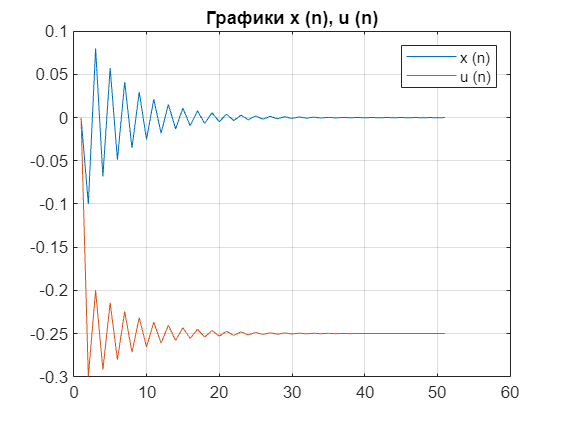

x = 1:1:n+1;
plot (x,X_bar); grid on;
title ('Графики x (n), u (n)');
legend ('x (n)', 'u (n)');

y=0.02

x0 = [0;0];
gradJ0 = [4*x0(2) + 16*x0(1) + 1; 12*x0(2) + 4*x0(1) + 3];
y = 0.02;

n = 50;
J = zeros (1, n+1);
X_bar = zeros (2, n+1);
X_bar (1,1) = x0 (1);
X_bar (2,1) = x0 (2);
J(1) = 8*x0(1)^2+6*x0(2)^2+4*x0(1)*x0(2)+x0(1)+3*x0(2)-10;
for i = 1:n
    xn = x0 - y*gradJ0;
    x0 = xn;
    X_bar (1,i+1) = x0 (1);
    X_bar (2,i+1) = x0 (2);
    gradJ0 = [4*x0(2) + 16*x0(1) + 1; 12*x0(2) + 4*x0(1) + 3];
    J(i+1) = 8*x0(1)^2+6*x0(2)^2+4*x0(1)*x0(2)+x0(1)+3*x0(2)-10;
end
xn

xn =    -0.0000
   -0.2500


J(n)

ans = -10.3750

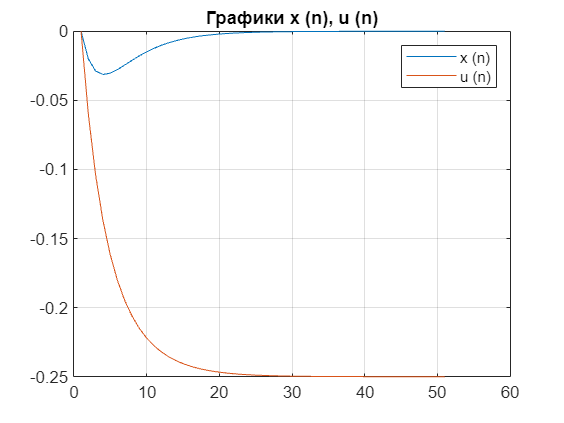

x = 1:1:n+1;
plot (x,X_bar); grid on;
title ('Графики x (n), u (n)');
legend ('x (n)', 'u (n)');